clear all
close all
clc

rng(1);

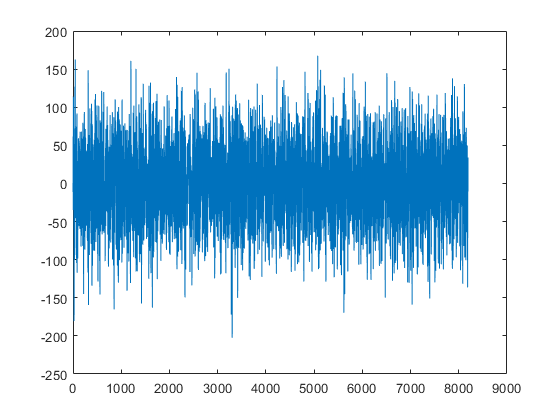


trainData = load('BoucWenFiles\bwdata.mat');
load('BoucWenFiles\Test signals\Validation signals\uval_multisine.mat')
load('BoucWenFiles\Test signals\Validation signals\yval_multisine.mat')

load('BoucWenFiles\Test signals\Validation signals\uval_sinesweep.mat')
load('BoucWenFiles\Test signals\Validation signals\yval_sinesweep.mat')

plot(uval_multisine)

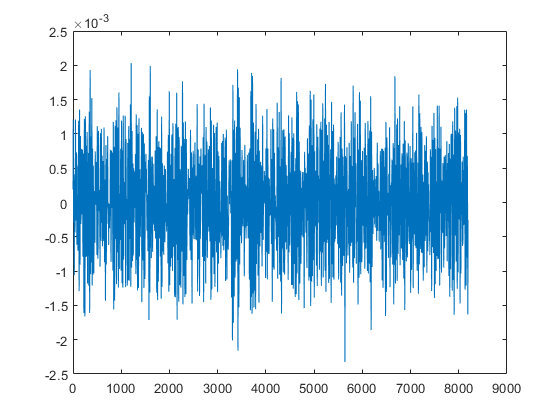

plot(yval_multisine)

Preprocessing Data

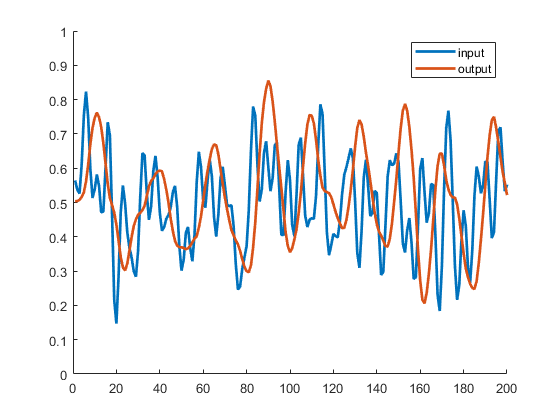

tic

input = trainData.bwdataz.u(:)/350+0.5;
output = 1000*trainData.bwdataz.y(:)/4+0.5;

tinput = uval_multisine'/350+0.5;
toutput = 1000*yval_multisine'/4+0.5;

tinput = uval_sinesweep'/350+0.5;
toutput = 1000*yval_sinesweep'/4+0.5;


input(input<0)=0;
output(output>1)=1;


% parcorr(input,30)
% parcorr(output,30)

figure
hold on
plot(input,'linewidth',2)
plot(output,'linewidth',2)
hold off
axis([0 200 0 1])
legend('input', 'output')

% histogram(input)
% histogram(output)



inlags=[1 2 3 4 6 8 10 12 14 16];
outlags=[0 1 2 3 4 8 12 16 20 24 28];

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 8;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 3.9872e-09



rez = [];

Optimize TT cores

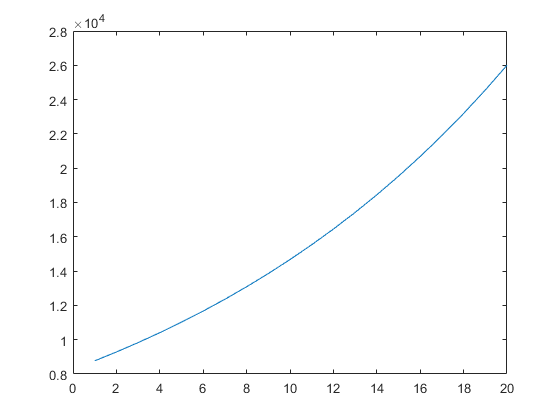

lambda=1*10^-8;

difforder=3;
MAXITR = d;


nselect = floor(logspace(log10(2*dof/N),-0.1,MAXITR)*N);
plot(nselect)


% MAXITR = d;
% nselect = ones([1,MAXITR])*N;


[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
rez = [rez res1];

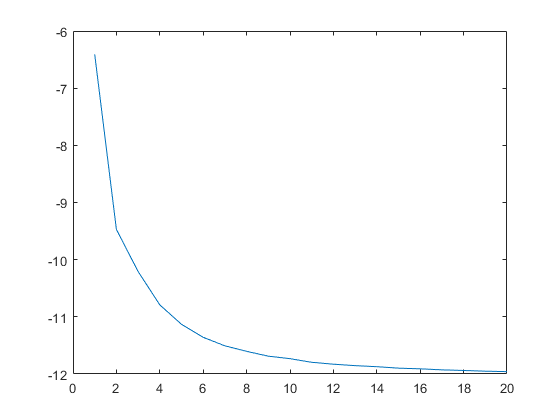


plot(log(res1))

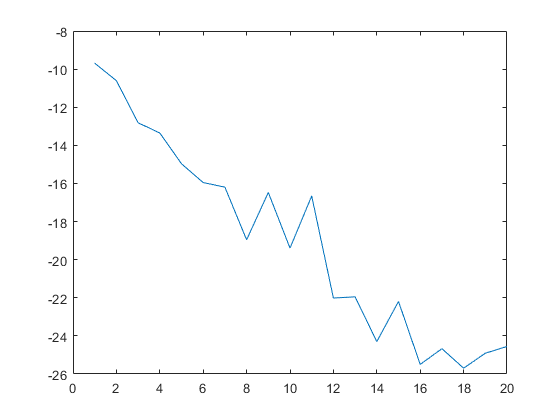

plot(log(res2))


trainerror = res1(end)

trainerror = 6.4044e-06


% plot(rez)

Evaluate Train data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9999

MSE = immse(yhat,yt)

MSE = 2.0313e-06



RMSE = sqrt(immse(1/250*yhat,1/250*yt))

RMSE = 5.7010e-06

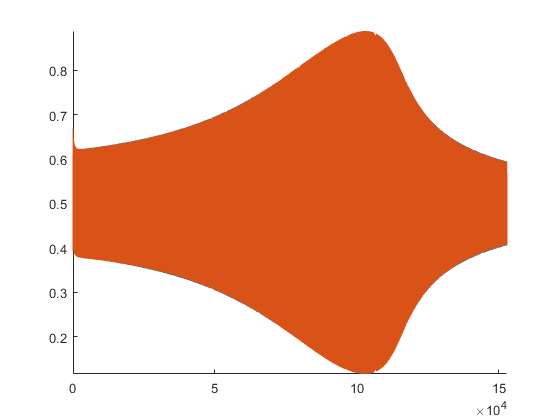


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

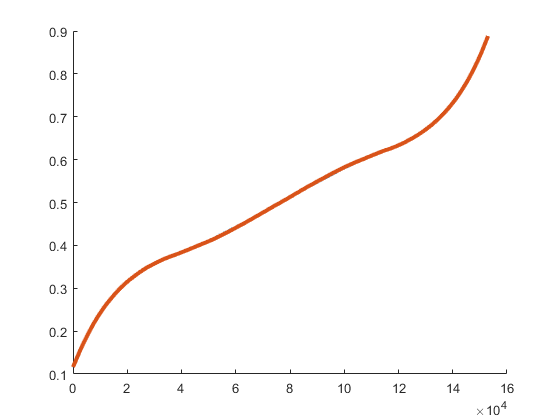


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off


% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off



% siminput = tinput;
% simoutput = toutput;
% numz = numel(outlags);
% beginz = max(outlags(end),inlags(end)) +1;
% for j = beginz+300:length(tinput)
% simfeaturez = [simoutput(j-outlags(end:-1:2))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
% simoutput(j) = evalspline(TN,simfeaturez,n,m);
% end

[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);

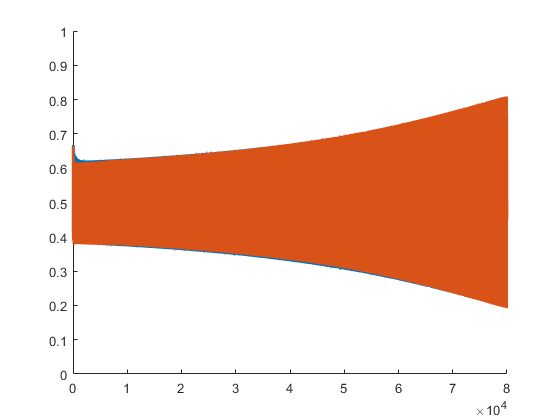

figure
hold on
plot(toutput(1:length(simoutput)),'linewidth',2)
plot(simoutput(1:length(simoutput)),'linewidth',2)
hold off
axis([0 80000 0 1])

RMSE = sqrt(immse(1/250*toutput,1/250*simoutput))

RMSE = 2.1112e-05

% simfeaturez = tfeaturez;
% simfeaturez(boolean(eye(9)))
% 
% diag(ones(1,5),-1)
% 
% ones(5,2)
toc

Elapsed time is 1124.404023 seconds.
